# `PolarChart`** Examples**

**Overview**

The Polar`Chart` compares two line plots of cyclic data arranged around a circular (polar) axes. The chart data comprises:

- `AngularData` - an increasing numeric vector representing the independent variable.

- `RadialData` - a two-column matrix of data, each column of which is plotted against the `AngularData` around the circle.

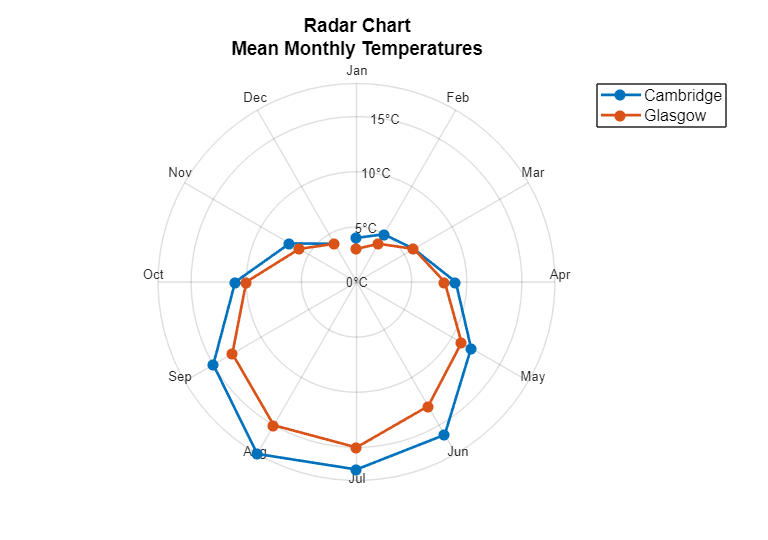

**Resources**

[Open](matlab: edit(fullfile(catalogRoot, "+example", "Radar.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot, "+chart", "Radar.m"))) the source code for the Polar`Chart`.

Documentation for:

- [`polaraxes`](matlab: doc("polaraxes")): create a polar axes

- [`polarplot`](matlab: doc("polarplot")): plot a line in polar coordinates

## Create sample chart data.

The angular data comprises the months of the year, and the radial data are the average monthly temperatures for two locations (Cambridge and Glasgow).

months = 1:12;
meanMonthlyTemps = [4, 5, 6, 9, 12, 16, 17, 18, 15, 11, 7, 4;
    3, 4, 6, 8, 11, 13, 15, 15, 13, 10, 6, 4].';

## Create a figure for the chart.

f = exampleFigure( "Name", "PolarChart Example" );

## Create the chart, specifying the parent and input data.

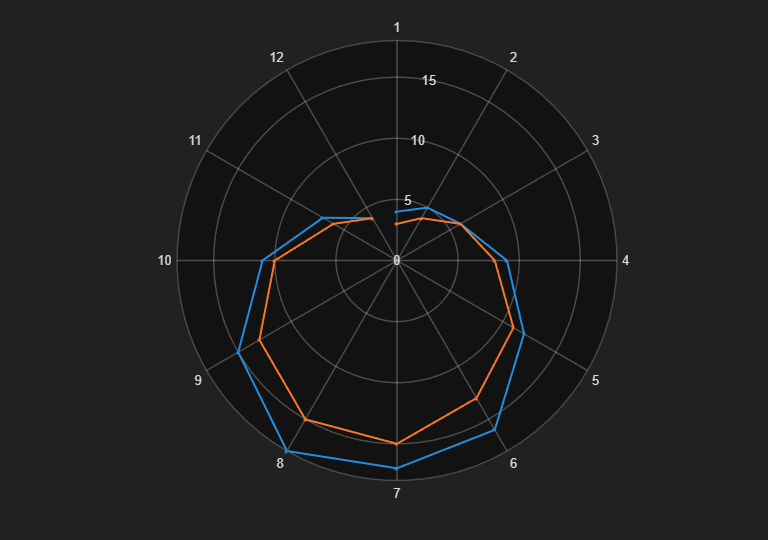

PC = PolarChart( "Parent", f, ...    
    "AngularData", months, ...
    "RadialData", meanMonthlyTemps );

## Annotate the chart.

Create and format the title.

title( PC, "Mean Monthly Temperatures", "FontSize", 14 )

Define and customize the legend entries.

legend( PC, ["Cambridge", "Glasgow"], ...
    "FontSize", 12, ...
    "Location", "northeastoutside" )

Customize the angular tick labels.

monthNames = month( datetime( 2000, 1:12, 1 ), "shortname" );
thetaticklabels( PC, monthNames )

Customize the radial tick labels.

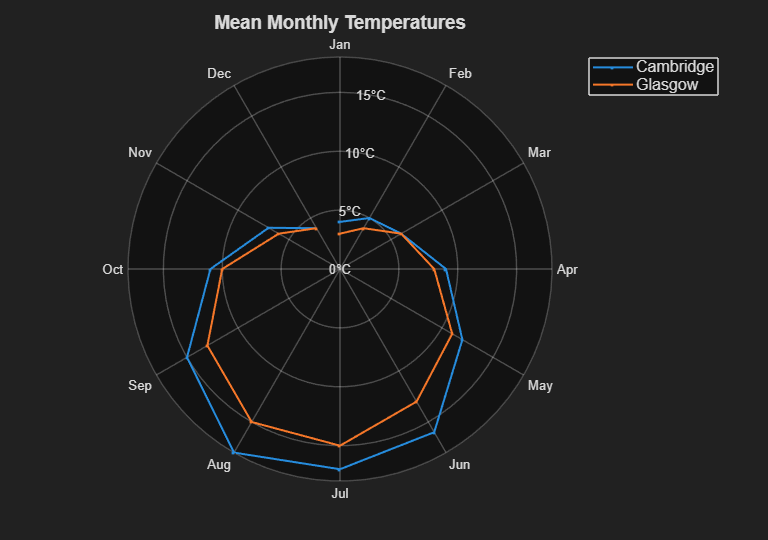

rticklabels( PC, rticklabels( PC ) + (char( 176 ) + "C") )

## Customize the chart appearance.

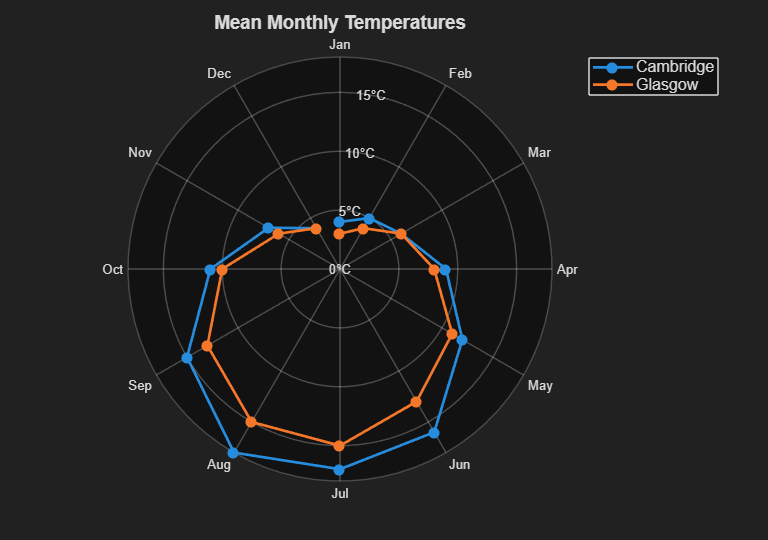

PC.MarkerSize = 25;
PC.LineWidth = 2;

## Change the underlying chart data.

First, compute the mean temperature in each quarter.

meanQuarterlyTemps = mean( reshape( meanMonthlyTemps, 3, [] ) );
meanQuarterlyTemps = reshape( meanQuarterlyTemps, [], 2 );

Update the angular data.

PC.AngularData = 1:4;

Update the radial data.

PC.RadialData = meanQuarterlyTemps;

Update the annotations.

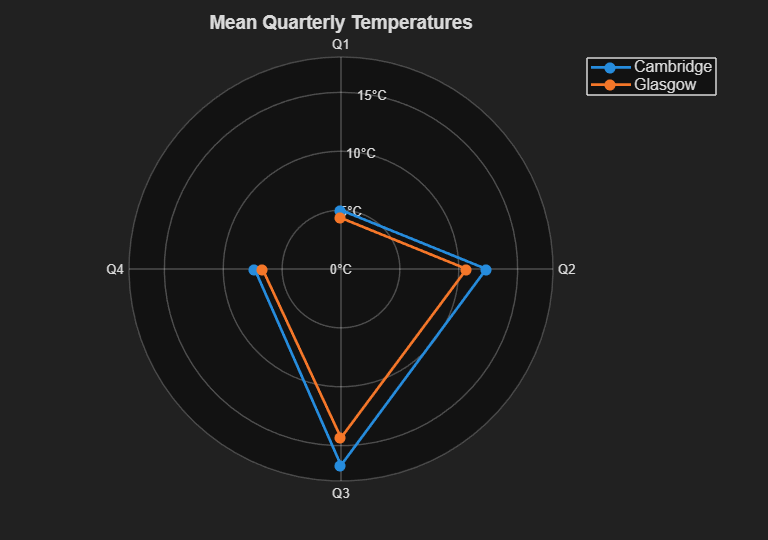

drawnow()
thetaticklabels( PC, "Q" + thetaticklabels( PC ) )
title( PC, "Mean Quarterly Temperatures" )

*Copyright 2018-2025 The MathWorks, Inc.*